# **Transmitter**

clc;
clear all;
close all;
no_of_data_bits = 64;   %no of bits per channel, it can be extended to 128
M = 4; %no of sub carrier channel
n = M*no_of_data_bits;   %Total no of bits to be transmitted to reciever side
block_size = 16; %size of each OFDM block to add cyclic prefix = no_of_data_bits/M
cp_len = floor(block_size/10);%length of the cyclic prefix

Generate random data source to be transmitted of length 64

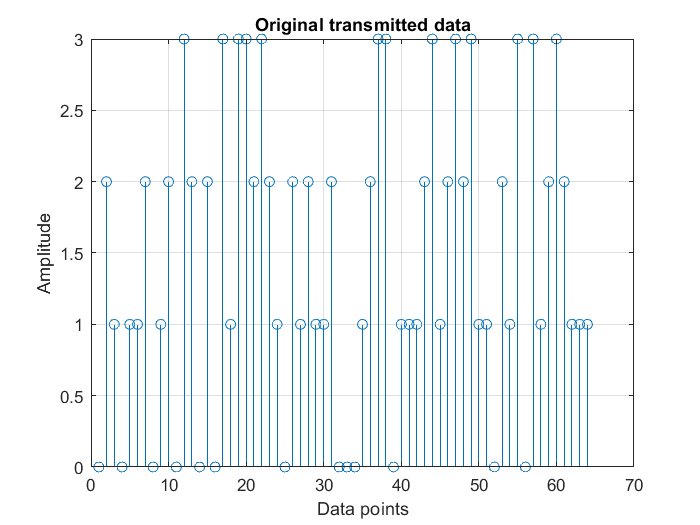

 data = randsrc(1, no_of_data_bits, 0:M-1);
 figure(1);
 stem(data);
 grid on
 xlabel('Data points');
 ylabel('Amplitude');
 title('Original transmitted data');

QPSK(Quadrature phase shift keying) Modulation on the input data source

 qpsk_modulated_data = pskmod(data,M);
 figure(2);
 stem(qpsk_modulated_data);

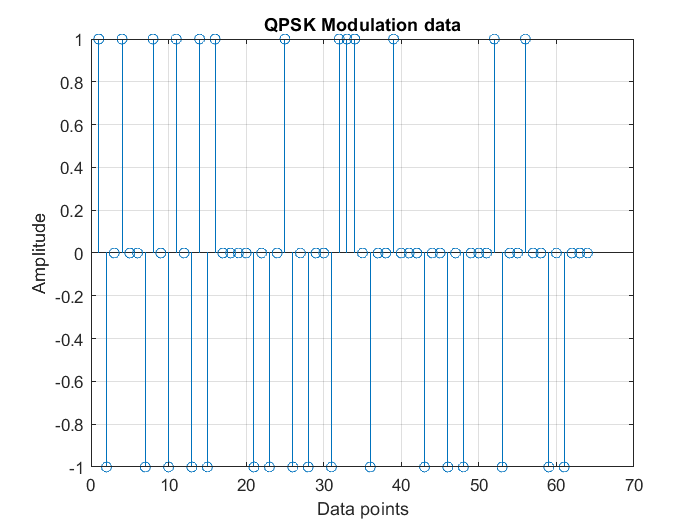

 grid on
 xlabel('Data points');
 ylabel('Amplitude');
 title('QPSK Modulation data');

Conversion into four sub carriers data from single data

 subcar = reshape( qpsk_modulated_data,no_of_data_bits/M, M );
 subcar1 = subcar(:,1);
 subcar2 = subcar(:,2);
 subcar3 = subcar(:,3);
 subcar4 = subcar(:,4);
 figure(3)
 subplot(4,1,1)
 stem((subcar1));

 grid on
 xlabel('Data points');
 ylabel('Amplitude');
 title('Sub carrier 1');
 subplot(4,1,2)
 stem(subcar2);

 grid on
 xlabel('Data points');
 ylabel('Amplitude');
 title('Sub carrier 2');
 subplot(4,1,3)
 stem(subcar3);

 grid on
 xlabel('Data points');
 ylabel('Amplitude');
 title('Sub carrier 3');
 subplot(4,1,4)
 stem(subcar4);

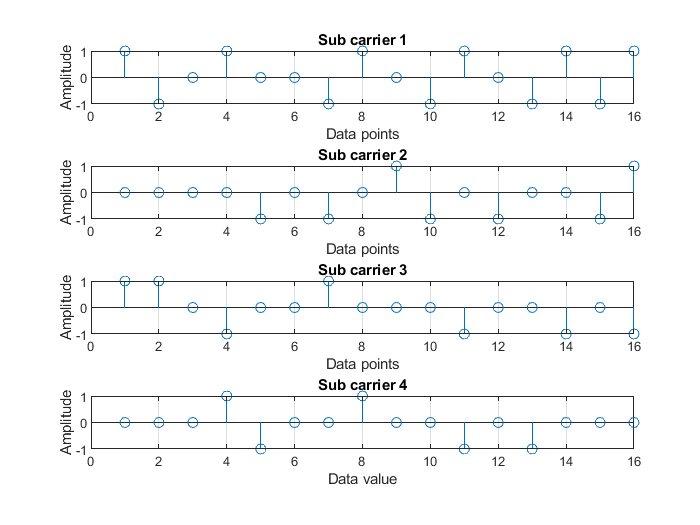

 grid on
 xlabel('Data value');
 ylabel('Amplitude');
 title('Sub carrier 4');

IFFT of four sub carriers

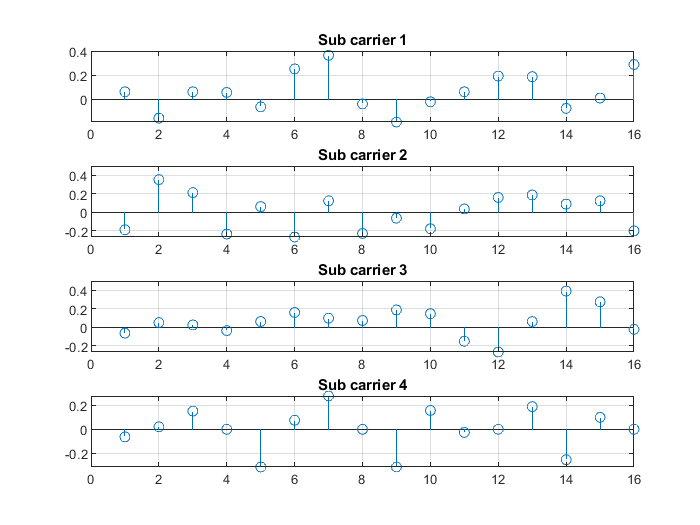

cp_start = block_size-cp_len;
ifft_subcar1=ifft(subcar1);
ifft_subcar2=ifft(subcar2);
ifft_subcar3=ifft(subcar3);
ifft_subcar4=ifft(subcar4); 
figure(4)
subplot(4,1,1)
stem(real(ifft_subcar1));
grid on
 title('Sub carrier 1');
 subplot(4,1,2)
 stem(real(ifft_subcar2));
 grid on
 title('Sub carrier 2');
 subplot(4,1,3)
 stem(real(ifft_subcar3));
 grid on
 title('Sub carrier 3');
 subplot(4,1,4)
 stem(real(ifft_subcar4));
 grid on
 title('Sub carrier 4');

Adding cyclic prefix

for i=1:M
    ifft_subcar(:,i) = ifft((subcar(:,i)) , block_size)
    for j= 1:cp_len
        cyclic_prefix(j,i) = ifft_subcar(j+cp_start,i);
    end
    append_prefix(:,i) = vertcat(cyclic_prefix(:,i), ifft_subcar(:,i));    %appends prefix to each sub carrier
end

ifft_subcar =    0.0625 + 0.1875i
  -0.1560 + 0.0000i
   0.0625 + 0.0107i
   0.0574 - 0.2134i
  -0.0625 - 0.1875i
   0.2517 - 0.0000i
   0.3643 - 0.3643i
  -0.0383 - 0.0366i
  -0.1875 + 0.1875i
  -0.0207 - 0.0000i


ifft_subcar =    0.0625 + 0.1875i  -0.1875 + 0.0625i
  -0.1560 + 0.0000i   0.3532 - 0.1317i
   0.0625 + 0.0107i   0.2134 - 0.0000i
   0.0574 - 0.2134i  -0.2338 + 0.0067i
  -0.0625 - 0.1875i   0.0625 - 0.0625i
   0.2517 - 0.0000i  -0.2657 - 0.0028i
   0.3643 - 0.3643i   0.1250 - 0.5152i
  -0.0383 - 0.0366i  -0.2274 - 0.0546i
  -0.1875 + 0.1875i  -0.0625 - 0.0625i
  -0.0207 - 0.0000i  -0.1764 - 0.2950i


ifft_subcar =    0.0625 + 0.1875i  -0.1875 + 0.0625i  -0.0625 + 0.0625i
  -0.1560 + 0.0000i   0.3532 - 0.1317i   0.0513 + 0.0061i
   0.0625 + 0.0107i   0.2134 - 0.0000i   0.0259 + 0.2027i
   0.0574 - 0.2134i  -0.2338 + 0.0067i  -0.0354 - 0.0219i
  -0.0625 - 0.1875i   0.0625 - 0.0625i   0.0625 + 0.1875i
   0.2517 - 0.0000i  -0.2657 - 0.0028i   0.1604 + 0.1279i
   0.3643 - 0.3643i   0.1250 - 0.5152i   0.0991 + 0.0991i
  -0.0383 - 0.0366i  -0.2274 - 0.0546i   0.0737 - 0.0354i
  -0.1875 + 0.1875i  -0.0625 - 0.0625i   0.1875 + 0.0625i
  -0.0207 - 0.0000i  -0.1764 - 0.2950i   0.1469 + 0.0457i


ifft_subcar =    0.0625 + 0.1875i  -0.1875 + 0.0625i  -0.0625 + 0.0625i  -0.0625 + 0.1875i
  -0.1560 + 0.0000i   0.3532 - 0.1317i   0.0513 + 0.0061i   0.0207 + 0.3401i
   0.0625 + 0.0107i   0.2134 - 0.0000i   0.0259 + 0.2027i   0.1509 - 0.0991i
   0.0574 - 0.2134i  -0.2338 + 0.0067i  -0.0354 - 0.0219i  -0.0000 - 0.0884i
  -0.0625 - 0.1875i   0.0625 - 0.0625i   0.0625 + 0.1875i  -0.3125 - 0.3125i
   0.2517 - 0.0000i  -0.2657 - 0.0028i   0.1604 + 0.1279i   0.0749 - 0.1091i
   0.3643 - 0.3643i   0.1250 - 0.5152i   0.0991 + 0.0991i   0.2759 - 0.1509i
  -0.0383 - 0.0366i  -0.2274 - 0.0546i   0.0737 - 0.0354i   0.0000 + 0.0884i
  -0.1875 + 0.1875i  -0.0625 - 0.0625i   0.1875 + 0.0625i  -0.3125 - 0.3125i
  -0.0207 - 0.0000i  -0.1764 - 0.2950i   0.1469 + 0.0457i   0.1560 + 0.0135i


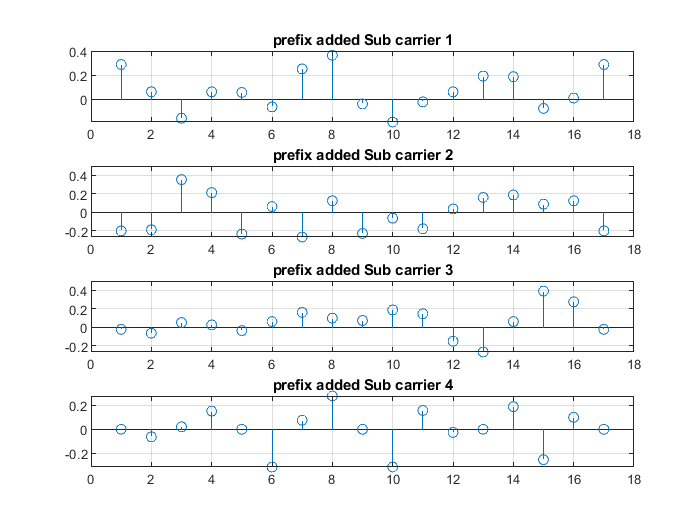

A1 = append_prefix(:,1);
A2 = append_prefix(:,2);
A3 = append_prefix(:,3);
A4 = append_prefix(:,4);
figure(5)
subplot(4,1,1)
stem(real(A1));
grid on
 title('prefix added Sub carrier 1');
 subplot(4,1,2)
 stem(real(A2));
 grid on
 title('prefix added Sub carrier 2');
 subplot(4,1,3)
 stem(real(A3));
 grid on
 title('prefix added Sub carrier 3');
 subplot(4,1,4)
 stem(real(A4));
 grid on
 title('prefix added Sub carrier 4');

OFDM signal to be transmitted

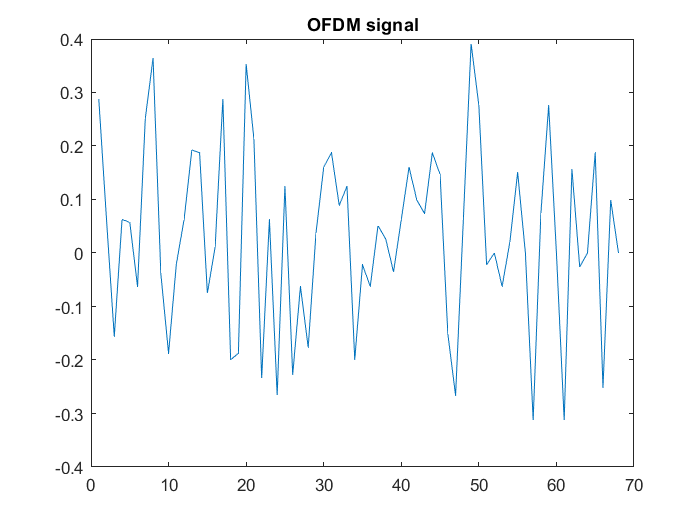

len_ofdm_data = no_of_data_bits+M*cp_len;
 ofdm_signal = reshape(append_prefix, 1, len_ofdm_data);
figure(6)
plot(real(ofdm_signal));
title('OFDM signal');

# Reciever

Passing through AWGN channel

channel = randn(1,2)+1i*randn(1,2);
after_channel = filter(channel, 1, ofdm_signal);
awgn_noise = awgn(zeros(1, length(after_channel)) , 0);
recieved_signal = awgn_noise+ after_channel   %recieved signal with awgn noise

recieved_signal =   -0.5780 + 0.0535i  -0.1012 + 0.4635i   2.2028 - 0.0492i   2.3803 - 0.3757i  -1.6356 + 0.4149i   1.0466 + 0.5956i   0.6706 + 0.0510i  -0.3882 + 1.0693i  -0.5000 + 1.2663i   1.5285 - 0.3008i  -0.2369 - 0.6279i  -0.9665 - 0.5241i  -1.2235 + 0.0564i   1.0248 + 0.2603i   0.9091 + 0.1154i   0.0195 - 0.1600i  -0.5704 + 0.0893i   0.6595 + 0.8641i  -0.2592 - 0.4242i   0.1536 - 0.3206i  -0.1942 + 0.9599i  -0.3291 + 0.4829i  -0.9760 - 0.4674i   0.0825 + 0.2077i  -1.9203 + 0.0620i   1.9297 + 0.8839i  -0.1355 - 0.3924i   0.9382 + 0.3015i   0.3879 - 0.1081i   0.9401 - 0.1345i  -1.8923 + 0.1214i   0.2029 + 0.4661i   0.1656 + 0.2613i  -0.2629 + 0.4314i   0.0610 + 0.0096i   2.4488 + 0.1380i  -1.5997 - 0.2161i   0.2270 - 0.1519i  -0.8802 - 0.1187i  -0.4617 - 0.3042i  -0.0189 - 0.2106i   0.5801 + 0.1144i   0.3876 + 0.1770i  -0.1101 + 0.1293i   0.6080 + 0.3151i   0.0792 + 0.7212i   1.2897 - 0.1178i   0.5631 - 0.6117i  -0.9760 + 0.7794i  -0.4149 + 0.9929i


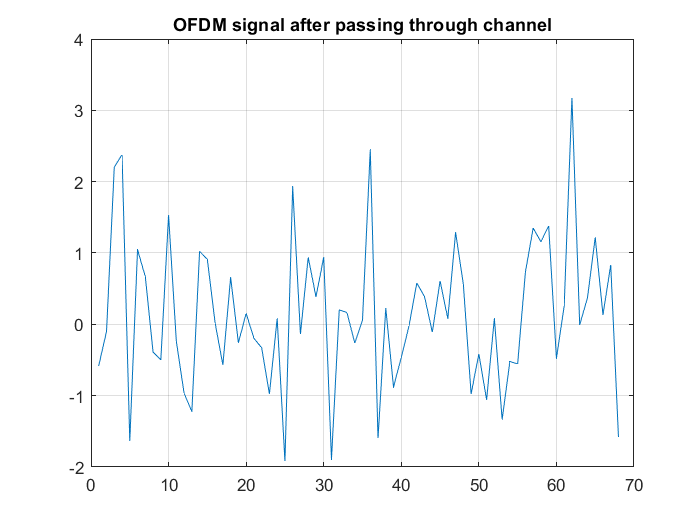

figure(7)
plot(real(recieved_signal));
title('OFDM signal after passing through channel');
grid on

Removing cyclic prefix

rows_append_prefix = len_ofdm_data/M;
cols_append_prefix = M;
recieved_signal_paralleled = reshape(recieved_signal , rows_append_prefix, cols_append_prefix)

recieved_signal_paralleled =   -0.5780 + 0.0535i   0.6595 + 0.8641i   0.0610 + 0.0096i   0.0844 + 0.1053i
  -0.1012 + 0.4635i  -0.2592 - 0.4242i   2.4488 + 0.1380i  -1.3341 - 0.3370i
   2.2028 - 0.0492i   0.1536 - 0.3206i  -1.5997 - 0.2161i  -0.5210 - 0.7818i
   2.3803 - 0.3757i  -0.1942 + 0.9599i   0.2270 - 0.1519i  -0.5558 - 0.1665i
  -1.6356 + 0.4149i  -0.3291 + 0.4829i  -0.8802 - 0.1187i   0.7315 + 0.5678i
   1.0466 + 0.5956i  -0.9760 - 0.4674i  -0.4617 - 0.3042i   1.3499 + 0.4935i
   0.6706 + 0.0510i   0.0825 + 0.2077i  -0.0189 - 0.2106i   1.1580 - 0.2631i
  -0.3882 + 1.0693i  -1.9203 + 0.0620i   0.5801 + 0.1144i   1.3806 + 0.4886i
  -0.5000 + 1.2663i   1.9297 + 0.8839i   0.3876 + 0.1770i  -0.4770 + 0.6799i
   1.5285 - 0.3008i  -0.1355 - 0.3924i  -0.1101 + 0.1293i   0.2563 + 0.3130i


recieved_signal_paralleled(1:cp_len,:) = [];
R1 = recieved_signal_paralleled(:,1);
R2 = recieved_signal_paralleled(:,2);
R3 = recieved_signal_paralleled(:,3);
R4 = recieved_signal_paralleled(:,4);

FFT of recieved signal

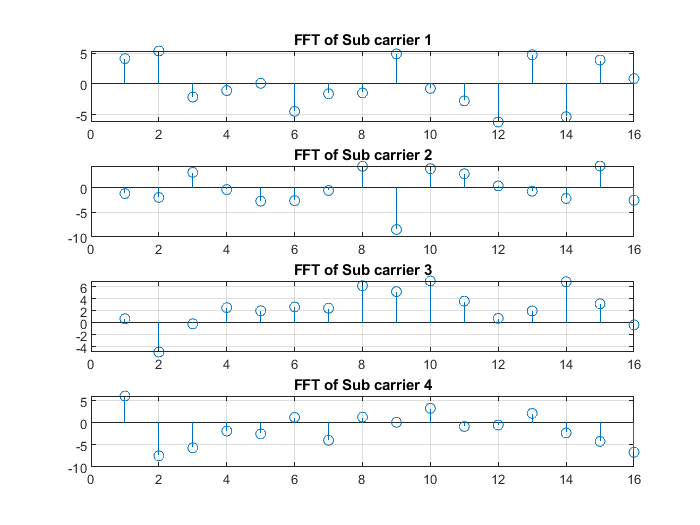

for i=1:M
    fft_signal(:,i) = fft(recieved_signal_paralleled(:,i),block_size);
end
F1 = fft_signal(:,1);
F2 = fft_signal(:,2);
F3 = fft_signal(:,3);
F4 = fft_signal(:,4);
figure(8)
subplot(4,1,1)
stem(real(F1));
grid on
 title('FFT of Sub carrier 1');
 subplot(4,1,2)
 stem(real(F2));
 grid on
 title('FFT of Sub carrier 2');
 subplot(4,1,3)
 stem(real(F3));
 grid on
 title('FFT of Sub carrier 3');
 subplot(4,1,4)
 stem(real(F4));
 grid on
 title('FFT of Sub carrier 4');

Demodulation of recieved signal

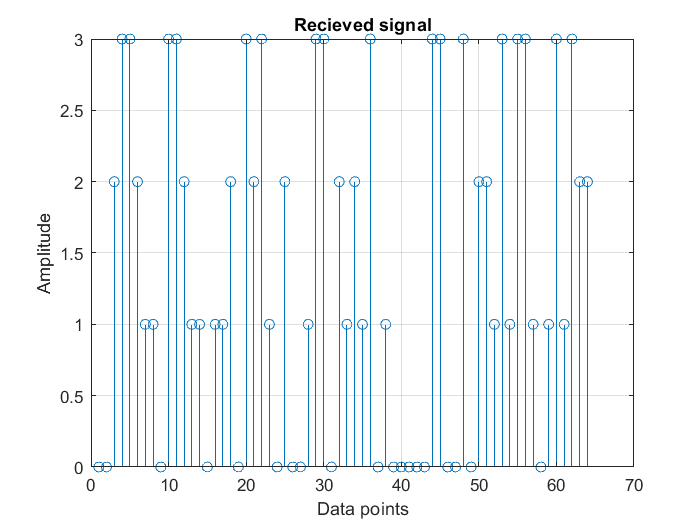

recieved_signal_data = reshape(fft_signal, 1, M*block_size);
qpsk_demodulated_data = pskdemod(recieved_signal_data,M);
figure(9)
stem(qpsk_demodulated_data);
grid on
xlabel('Data points');
ylabel('Amplitude');
title('Recieved signal');